# **TU: SVM classification**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

mod: 2024-2

## Introduction

Classification with SVM

## Example: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

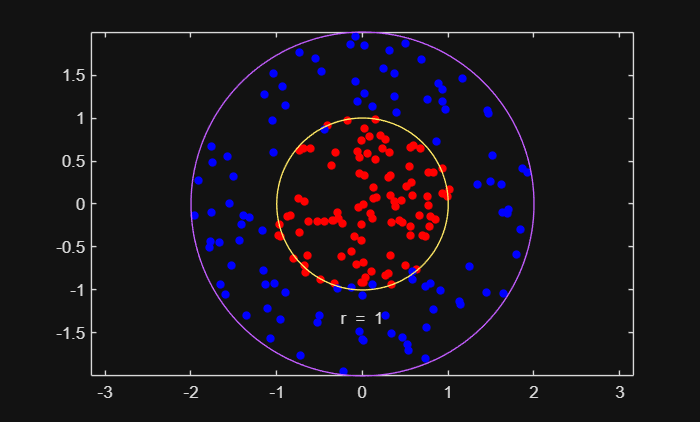

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1*rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% Class y=1
r2 = sqrt(3*rand(100,1)+0.9); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

% With Box Constraint =inf
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);


% With Box Constraint default - Also check the result
% cl = fitcsvm(dataC,theclass,'KernelFunction','rbf');


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

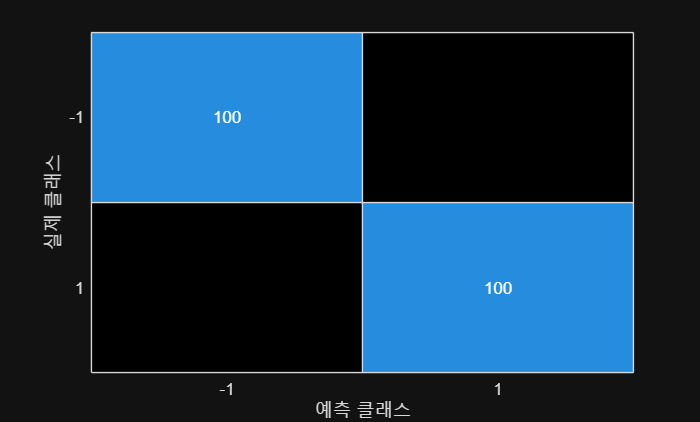

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

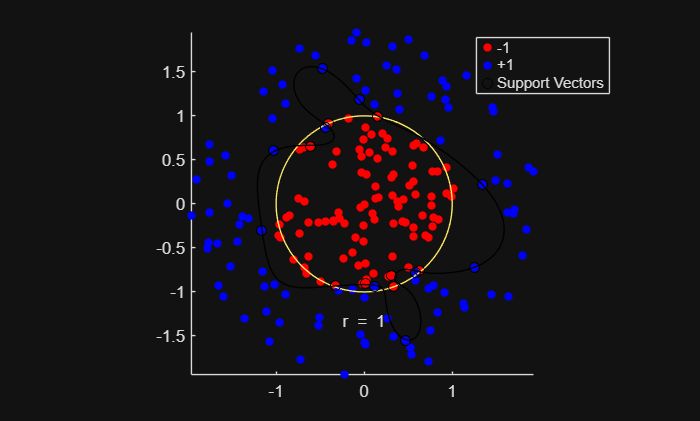

figure;
h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
    NumObservations: 200
        NumTestSets: 10
          TrainSize: [180 180 180 180 180 180 180 180 180 180]
           TestSize: [20 20 20 20 20 20 20 20 20 20]
           IsCustom: 0
          IsGrouped: 0
       IsStratified: 1


  Properties, Methods



cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0800

# Exercise  

## Exercise 1: SVM Classification with CWRU (binary class)

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

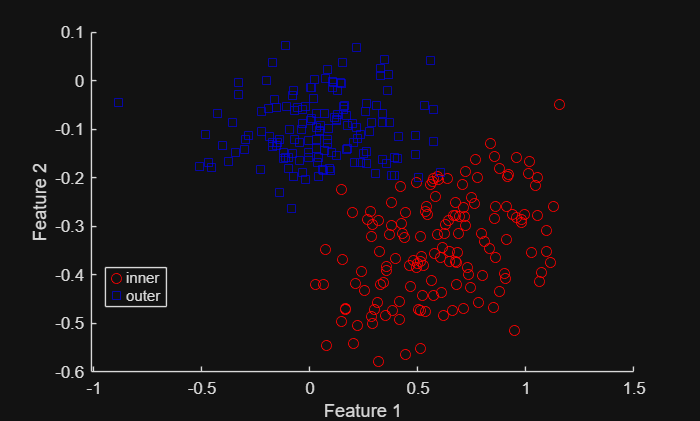

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../IAIA/Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate k=10 disjoint stratified subsets.

cv = cvpartition(Y,'KFold',10)

cv = K-겹 교차 검증 분할
    NumObservations: 288
        NumTestSets: 10
          TrainSize: [260 259 259 259 259 259 259 259 259 260]
           TestSize: [28 29 29 29 29 29 29 29 29 28]
           IsCustom: 0
          IsGrouped: 0
       IsStratified: 1


  Properties, Methods


###  Train SVM 

% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})

cl = fitcsvm(X, Y, 'KernelFunction', 'rbf', 'BoxConstraint', Inf, 'ClassNames', {'outer','inner'})

cl =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'outer'  'inner'}
           ScoreTransform: 'none'
          NumObservations: 288
                    Alpha: [4×1 double]
                     Bias: 36.3541
         KernelParameters: [1×1 struct]
           BoxConstraints: [288×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [288×1 logical]
                   Solver: 'SMO'


  Properties, Methods


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

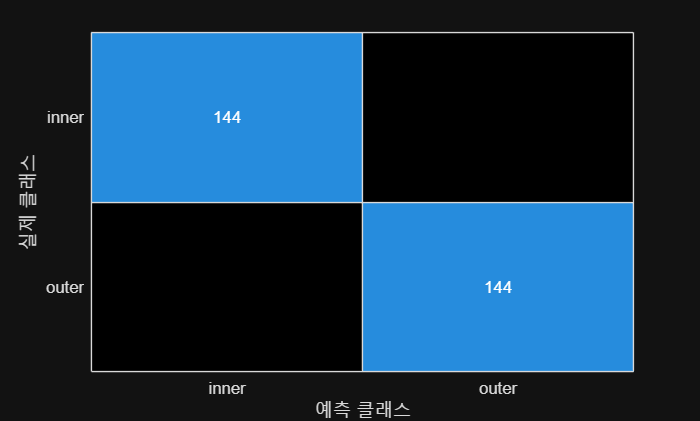

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(Y,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

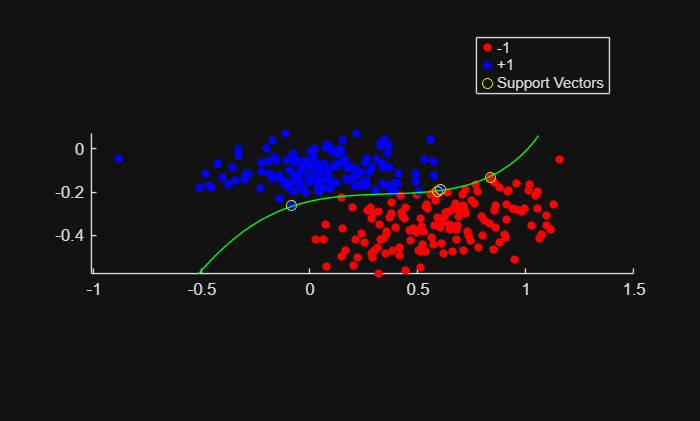

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on
h(3) = plot(X(cl.IsSupportVector,1),X(cl.IsSupportVector,2),'yo');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'g');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

cvml = crossval(cl,'CVPartition', cv);

Cross validate and show cv loss

mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0104

## Exercise 2: SVM Classification with CWRU (3 classes)

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

% Example
clear;
load("../IAIA/Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Analyze  the test and train results 

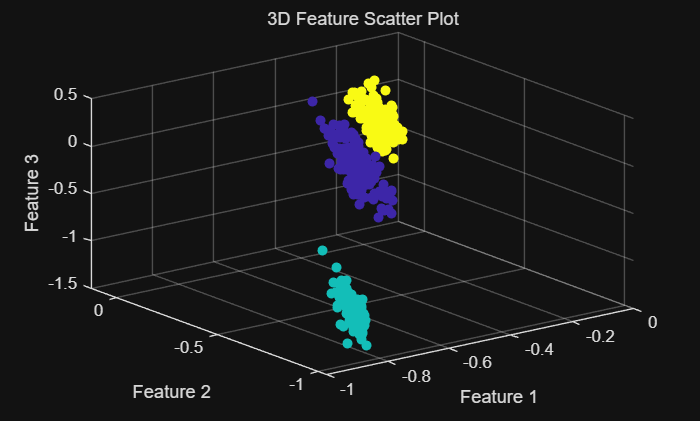

Y = class_cwru_train;
N = size(X,1);

figure;
g = categorical(Y);
scatter3(X(:,1), X(:,2), X(:,3), 36, g, 'filled')
xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Feature 3');
grid on
title('3D Feature Scatter Plot');

### CV Partition

cvpartition은 데이터(Y)를 10개의 층화된 폴드로 분리

클래스 비율을 유지하멸서 자동으로 분리 해준다.

나중에 crossval()에서 사용하기 위해 미리 분리

분리된 데이터로 교차 검증을 함으로 overfitting을 줄인다.

cv = cvpartition(Y, 'KFold', 10)

cv = K-겹 교차 검증 분할
    NumObservations: 432
        NumTestSets: 10
          TrainSize: [389 388 388 389 389 389 389 389 389 389]
           TestSize: [43 44 44 43 43 43 43 43 43 43]
           IsCustom: 0
          IsGrouped: 0
       IsStratified: 1


  Properties, Methods


### Train SVM

kernelfunction = 'rbf' (=radial basis function) 비선형 커널

boxconstraint = 1 오류를 허용치 결정 값 c가 작을수록 soft margin 클수록 hard margin

fitcsvm는 이진 데이터만 가능 -> fitcecoc으로 multi class svm 학습 가능

t = templateSVM('KernelFunction','rbf', 'BoxConstraint',1);

% Multi-class SVM
cl = fitcecoc(X, Y, 'Learners', t, 'ClassNames', {'normal','inner','outer'});

Loss and confusion matrix

mlResubErr = resubLoss(cl)

mlResubErr = 0

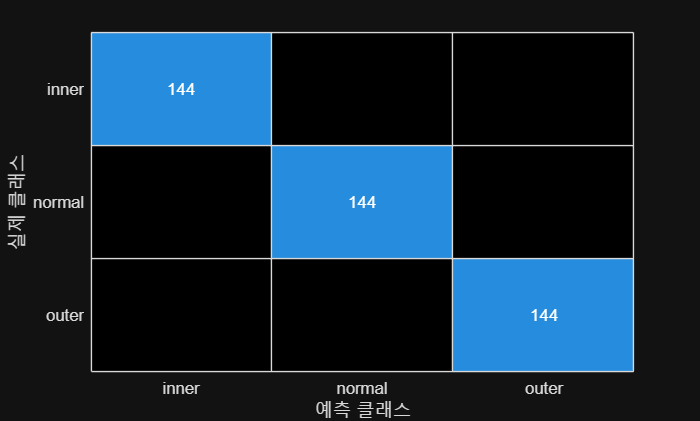

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(Y,mlClass);

Predict scores over the grid

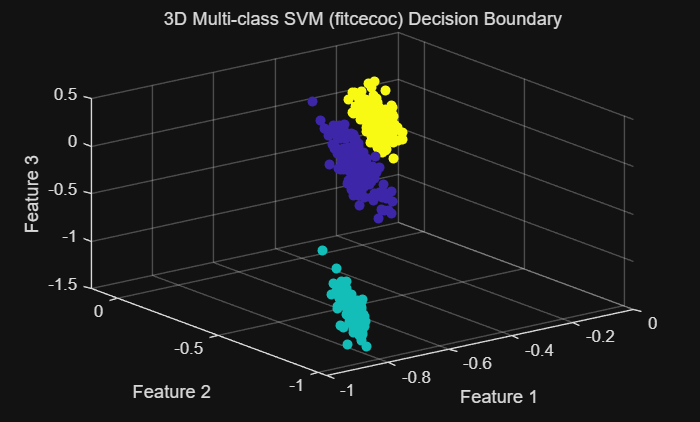

figure;

g = categorical(Y);
scatter3(X(:,1), X(:,2), X(:,3), 36, g, 'filled');
hold on; grid on;

d = 0.1;
[x1Grid, x2Grid, x3Grid] = meshgrid( ...
    min(X(:,1)):d:max(X(:,1)), ...
    min(X(:,2)):d:max(X(:,2)), ...
    min(X(:,3)):d:max(X(:,3)));

gridPoints = [x1Grid(:), x2Grid(:), x3Grid(:)];
[~, scores] = predict(cl, gridPoints);
 
% scoreGrid = reshape(scores(:,1), size(x1Grid)); % ECOC 첫 classifier 점수
% 
% xs = mean(X(:,1));
% ys = mean(X(:,2));
% zs = mean(X(:,3));
% 
% h = slice(x1Grid, x2Grid, x3Grid, scoreGrid, xs, ys, zs);
% set(h,'EdgeColor','none','FaceAlpha',0.5);

xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Feature 3');
title('3D Multi-class SVM (fitcecoc) Decision Boundary');
hold off;

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

cvml = crossval(cl,'CVPartition', cv);

Cross validate and show cv loss

mlCVErr = kfoldLoss(cvml)

mlCVErr = 0

accSVM = 1 - mlCVErr;

Compare performance of SVM with  other models such as Logistic Regression

tLR = templateLinear('Learner','logistic');
modelLR = fitcecoc(X, Y, 'Learners', tLR, 'Coding','onevsall');


% cvLR = crossval(modelLR, 'CVPartition', cv);
% lossLR = kfoldLoss(cvLR);
% accLR = 1 - lossLR;
% 
% fprintf('SVM (RBF ECOC) Accuracy:        %.4f\n', accSVM);
% fprintf('Logistic Regression Accuracy:   %.4f\n', accLR);